# Calcium plot

this code is to plot calcium imaging signals. What's required is a csv file containing intensity of ROIs. Started on Oct 29th 2019. Last edited by Lijun on May 5th, 2022

#### Read Table and plot heatmap

close all
clearvars -except path
% addpath('C:\Users\Qi_Li\Dropbox (HMS)\code\LQ_calcium_matlab');
fps = 10; % frequency in Hz, change this when using different settings

if exist('path', 'var') == 0 || isempty(path) || ~ischar(path)
    [filename,path] = uigetfile('E:\Dropbox (HMS)\LQCalciumImaging1\analysis\*.csv');
else
    [filename, path] = uigetfile(fullfile(path,'*.csv'));
end

% initialPlot is a function for us to get a first and general idea of how
% the data looks like. Bleach correction is only suggested when the
% calcium spikes are short or when the recording session is longer than
% 120s

normDeltaF = initialProcess(path, filename, fps, 'bleach correction', 6, 0.975); %for forceSine

% normDeltaF = initialProcess(path, filename, fps); for Indentation 

% for the thermal stimulation, split them into 10 files and save. Make sure you use
% the same stimulation file: starting from 35, ending at 55 C
if size(normDeltaF, 1) == 9000
    temperature = [35, 25, 20, 40, 15, 45, 10, 50, 5, 55];
    T = readtable(fullfile(path, filename));
    n = size(T, 1)/10;
    for i = 1:10
        Tsplit = T(1+n*(i-1):i*n,:);
        writetable(Tsplit, fullfile(path, ['peltier_', num2str(temperature(i)),'C.csv']));
    end
end

#### If happy with the figure, save it

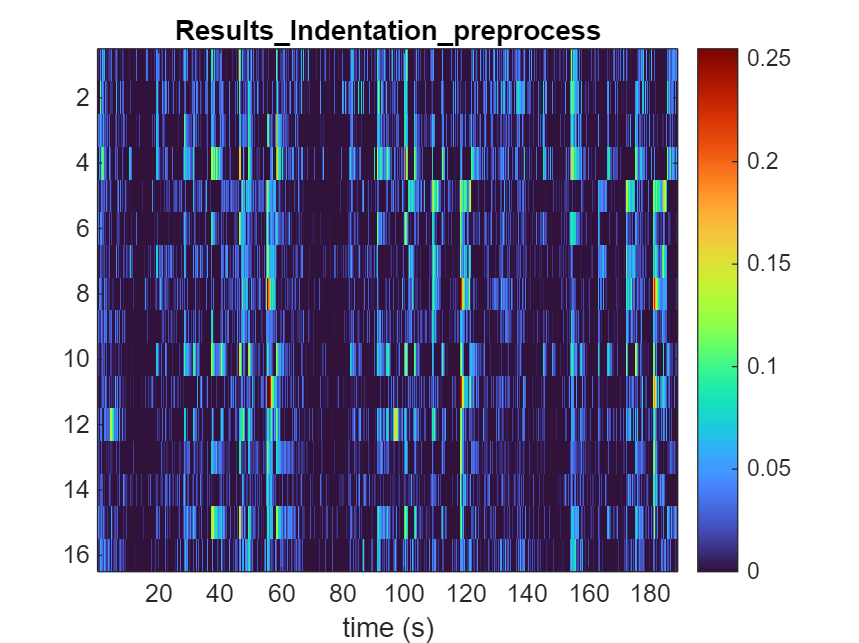

if (1)
    pathparts = strsplit(path,filesep);
    mouseID = pathparts{end-1}; clear pathparts
    name = [filename(1:end-4), '_', mouseID];
    t = title(name);
    set(t,'Interpreter','none')
    
    figureName = [path, name, '.jpg'];
    saveas(gcf,figureName)
    clear t
end

#### Save into structure called 'Data'

save the data into structure so it's easier to access in the future

structName = [path, 'Data.mat'];
if isfile(structName)
    load(structName);
else
    Data = struct;
    %data.info.mouseID = mouseID;
end

if contains(filename,"frey")  % the fieldname can't start with number
    filename = erase(filename, "von_frey");
    filename = strcat('von_frey',filename);    
end

Data.(filename(1:end-4)) =  normDeltaF;

save(structName, 'Data');

clear structName

#### Quatification and save the responsive ROIs into a structure

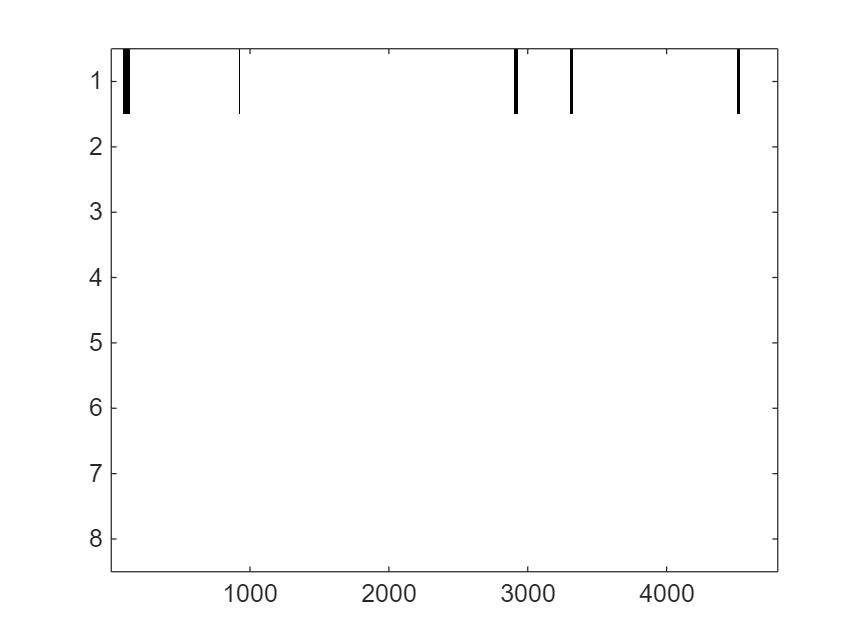

nStd = 7;%7; 
% the signal that is 'nStd' times of of standard deviation larger than noise (in baseline) is regarded as response 
% nStd can change depending on the sigal-to-noise ratio of imaging
% the baseline is the first 90 or 100 frames of the imaging averaged
[digitROI, responseROI0] = quantify(normDeltaF, filename, nStd);

#### Plot traces of all responsive neurons

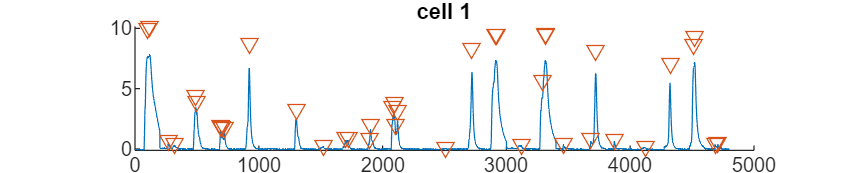

thresh = 0.1; 
spike0 = plotAllResponse(responseROI0, normDeltaF,path, filename, thresh, fps, ...
    "peakLabel", 1, 'NumFig', 60, 'save',0); 

% if "peakLabel" is 1, peaks will be labeled
% the spike0 contains the amplitude and timing of the peaks

#### Save the response information into two structure

% goodROI = [1, 2, 5, 7, 8, 10, 11, 20, 21, 24, 25, 26, 27 ]; badROI = setdiff(responseROI0, goodROI);
badROI = [];
[responseROI, responseIndex] = setdiff(responseROI0, badROI);
responseROI(2, :) = nStd; % nStd means the definition of response, stored in second line of responseROI
responseROI(3, 1:length(badROI)) = badROI;
spike = spike0(:, responseIndex,:);
% clear spike0 responseROI0

responseStructName = [path, 'responseROIstruct.mat'];
if isfile(responseStructName)
    load(responseStructName);
else
    responseROIstruct = struct;
end

responseROIstruct.(filename(1:end-4)) = responseROI;
% responseROIstruct.(filename(1:end-5)) = responseROI;

save(responseStructName, 'responseROIstruct');

spikeStructName = [path, 'spikeStruct.mat'];
if isfile(spikeStructName)
    load(spikeStructName);
else
    spikeStruct = struct;
end

spikeStruct.(filename(1:end-4)) = spike;
save(spikeStructName, 'spikeStruct');

#### Plot traces of certain neuron (optional)

If curious about what certain trace looks like, or what does bleach correction algorithm do to the trace

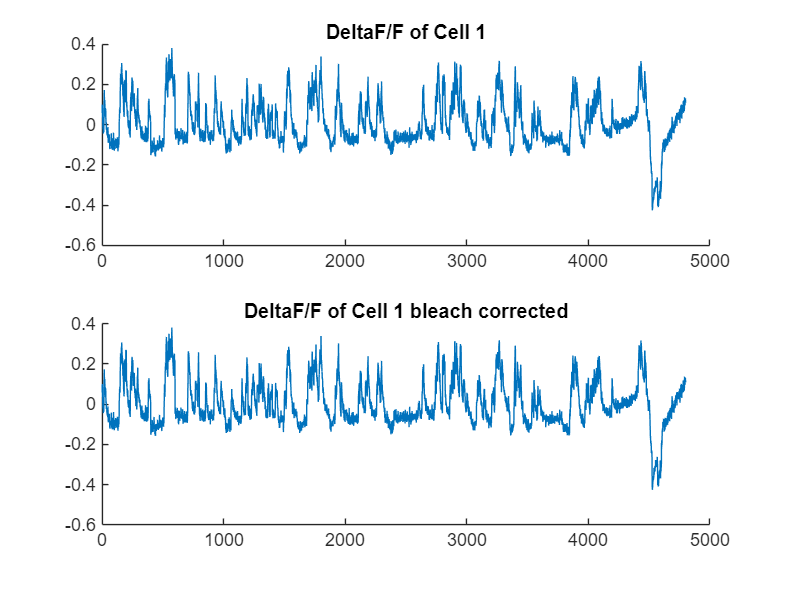


nCell = input('the neuron you are interesed in?  \n ');
figure,
subplot(211);
plot(normDeltaF(:,nCell)), title(['DeltaF/F of Cell ', num2str(nCell)]);
box off
% subplot(212),findpeaks(normDeltaF(:,nCell),'MinPeakProminence',thresh),title('Peaks');
[~, b, ~] = RobustDetrend(normDeltaF(:,nCell), 6, 0.975);
subplot(212), plot(b), 
title(['DeltaF/F of Cell ', num2str(nCell), ' bleach corrected']);
box off